nclear all;

# Planning a 5G Fixed Wireless Access Link over Terrain

Code for the WiNet project based on the "antenna_phased/SINRMapForA5GUrbanMacroCellTestEnvironmentExample" and the  "'5g_phased/CDLChannelModelCustomizationWithRayTracingExample' examples.

## Define the Global Parameters

Define the global parameters that will be used all over the code

fc = 1.899e9; % 1. GHz
freqRange = [1.7e9 2e9]

freqRange = 1.0e+09 *

    1.7000    2.0000


txPowerDBm = 23; % Overall transmit power inDBm
txPowerW = 10.^((txPowerDBm-30)/10); % Convert dBm to W
antHeightTx=18; % Mac height of the antenna
antHeightRx=14;

azimuthAngleTx = 60; % Antenna 3dB horizontal opening (azimuth) angle
elevationAngleTx= 11; % Antenna 3dB vertical opening (elevation) angle
azimuthAngleRx = 20; % Antenna 3dB horizontal opening (azimuth) angle
elevationAngleRx= 30; % Antenna 3dB vertical opening (elevation) angle

## Create Base Station Site in 3.75 GHz Band

Create a transmitter on the 5G trailer site. The overall antena is gonna be constructed using three of the same antenna so it can radiate in 360 degrees.

tx = txsite("Name","Trailer antenna (BS)", ...
    "Latitude",53.835668, ...
    "Longitude",10.696956, ...
    "AntennaHeight",antHeightTx, ...
    "TransmitterFrequency",fc, ...
    "TransmitterPower",txPowerW, ...
    "AntennaAngle",330);

## Create user equipment

Define the reciver antenas o user equipment. Create a 3-by-3 rectangular array from a reflector-backed vertical dipole antenna element. At each receiver site, point the array toward the base station and plot the radiation pattern on the map.

rx1 = rxsite("Name","UE1", ...
    "Latitude",53.834599, ...
    "Longitude",10.700833, ...
    "AntennaHeight",antHeightRx);
rx2 = rxsite("Name","UE2", ...
    "Latitude",53.835255, ...
    "Longitude",10.699859, ...
    "AntennaHeight",antHeightRx);

rx3 = rxsite("Name","UE3", ...
    "Latitude",53.833662, ...
    "Longitude",10.697437, ...
    "AntennaHeight",antHeightRx);

rx4 = rxsite("Name","UE4", ...
    "Latitude",53.836679, ...
    "Longitude",10.697858, ...
    "AntennaHeight",antHeightRx);

rx5 = rxsite("Name","UE5", ...
    "Latitude",53.837977, ...
    "Longitude",10.700569, ...
    "AntennaHeight",antHeightRx);
rx6 = rxsite("Name","UE6", ...
    "Latitude",53.832539, ...
    "Longitude",10.701414, ...
    "AntennaHeight",antHeightRx);

rxs = [rx1, rx2, rx3, rx4,rx5, rx6];


## Define the propagation model

Create a ray tracing propagation model

pm = propagationModel("raytracing","Method","sbr","AngularSeparation","low", ...
    "MaxNumReflections",10);

## Create Base Station Antenna Element

Section 8.5 of ITU-R report [1] defines antenna characteristics for base station antennas. The antenna is modeled as having one or more antenna panels, where each panel has one or more antenna elements. Use Phased Array System Toolbox to implement the antenna element pattern defined in the report.

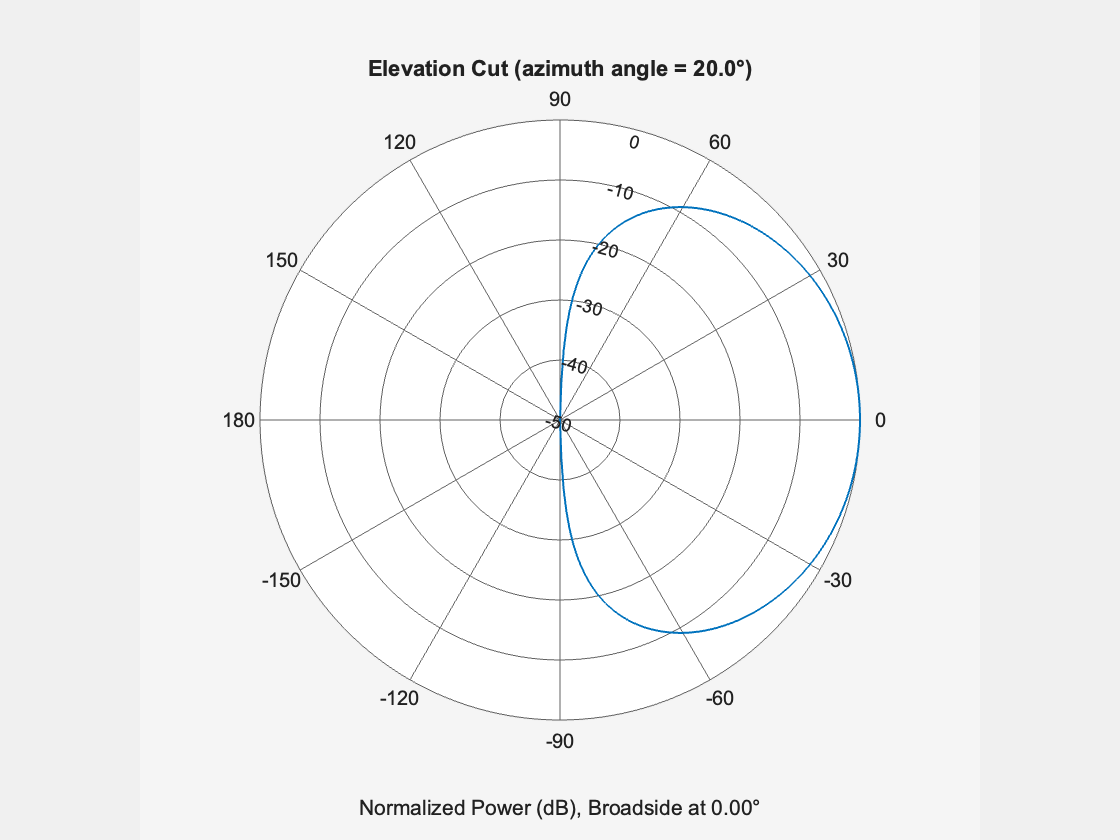

% Define pattern parameters
azang = -(azimuthAngleTx):(azimuthAngleTx);
elang = -(elevationAngleTx):(elevationAngleTx);
magpattern = mag2db(repmat(cosd(elang)',1,numel(azang)));
phasepattern = zeros(size(magpattern));

% Create antenna element
antennaElementTx = phased.CosineAntennaElement("FrequencyRange",freqRange);
   
% Display radiation pattern
pattern(antennaElementTx,fc,20,-90:90,'CoordinateSystem','polar','Type','powerdb')


% Create ULA
N = 3;   % Number of elements
R = 1;    % Radius (m)
txArray = phased.UCA('NumElements',N,'Radius',R,'Element',antennaElementTx);

tx.Antenna =antennaElementTx;

## Create User Equipment Antenna Element

Using the parameters defined in the project description, a custom antenna has been created 

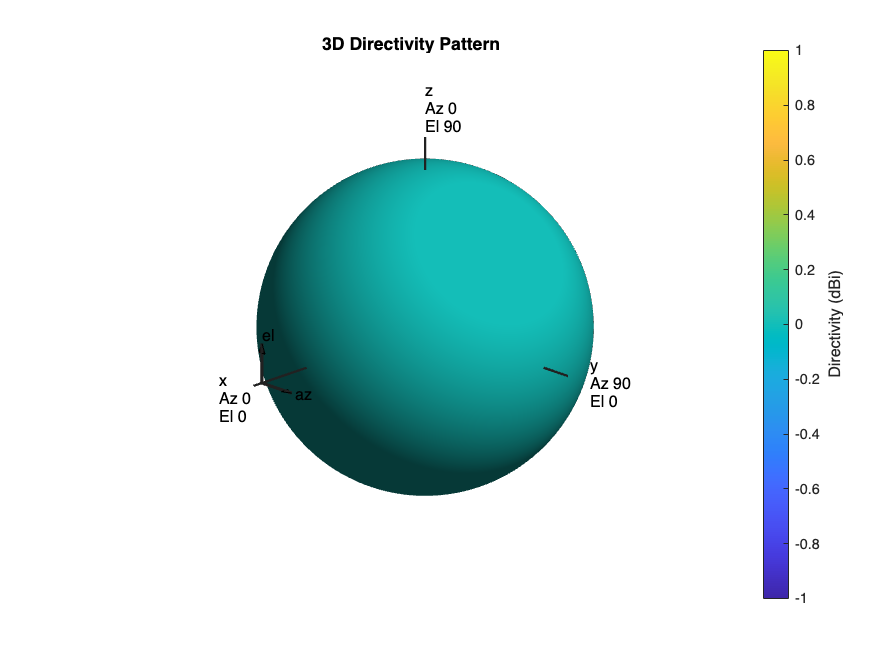

% Define pattern parameters
azang = -(azimuthAngleRx):(azimuthAngleRx);
elang = -(elevationAngleRx):(elevationAngleRx);
magpattern = mag2db(repmat(cosd(elang)',1,numel(azang)));
phasepattern = zeros(size(magpattern));
c=3e8;
lam=c/fc;
% Create antenna element
antennaElementRx = phased.IsotropicAntennaElement('FrequencyRange',freqRange);

   
% Display radiation pattern
pattern(antennaElementRx,fc,-180:180,-90:90,'CoordinateSystem','polar')

pattern(antennaElementRx,fc,20,-90:90,'CoordinateSystem','polar','Type','powerdb')
array = phased.URA('Element',antennaElementRx,'Size',[3 3],'ElementSpacing', ...
    [lam/2 lam/2],'ArrayNormal','y');
% pattern(array,fc,-180:180,-90:90,'PropagationSpeed',c, ...
%     'CoordinateSystem','polar','Type','powerdb','Normalize',true)
%Set the antenna element

% Assign array to each receiver site and point toward base station
for rx = rxs
    rx.Antenna = antennaElementRx;
    rx.AntennaAngle = angle(rx, tx);
end

## View the equipment and coverage

% Assign the antenna element for each cell transmitter




if exist('viewer','var') && isvalid(viewer) % viewer handle exists and viewer window is open
    clearMap(viewer);
else
    viewer = siteviewer("Basemap","openstreetmap","Buildings","CampusTHL_v2.osm");    
end

% Display all the equipment

show(rxs);
for rx = rxs
    pattern(rx,fc) %Display the radiation pattern of each UE
end
show(tx);
pattern(tx,fc);

% Display the coverage of the base station
coverage(tx, ...
    'PropagationModel',pm, ...
    'SignalStrengths',-100:-5, ...
    'MaxRange',500, ...
    "Resolution",5);

% Compute signal strength with foliage loss and weather
for rx = rxs
    ss = sigstrength(rx,tx,pm);
    disp("Signal strength at " + rx.Name + ":")
    disp(ss + " dBm")
end

Signal strength at UE1:


-52.8547 dBm


Signal strength at UE2:


-51.6341 dBm


Signal strength at UE3:


-61.3262 dBm


Signal strength at UE4:


-77.8855 dBm


Signal strength at UE5:


-76.5395 dBm


Signal strength at UE6:


-60.3329 dBm


## Display SINR Map for Single Antenna Element

Visualize SINR for the test scenario using a single antenna element and the free space propagation model. For each location on the map within the range of the transmitter sites, the signal source is the cell with the greatest signal strength, and all other cells are sources of interference. Areas with no color within the network indicate areas where the SINR is below the default threshold of -5 dB.



% Define receiver parameters using Table 8-2 (b) of Report ITU-R M.[IMT-2020.EVAL] 
bw = 100e6; % 20 MHz bandwidth
rxNoiseFigure = 7; % dB
rxNoisePower = -174 + 10*log10(bw) + rxNoiseFigure;
rxGain = 0; % dBi
rxAntennaHeight = 1.5; % m

% sinr(tx,'freespace', ...
%     'ReceiverGain',rxGain, ...
%     'ReceiverAntennaHeight',rxAntennaHeight, ...
%     'ReceiverNoisePower',rxNoisePower, ...    
%     'MaxRange',isd, ...
%     'Resolution',isd/20)


### Antenna definitions

function element = reflectorCrossedDipoleElement(fq, showAntenna)
%reflectorCrossedDipoleElement   Design reflector-backed crossed dipole antenna element

if nargin < 2
    showAntenna = false;
end

lambda = physconst("lightspeed")/fq;
offset = lambda/50;
gndspacing = lambda/4;
gndLength = lambda;
gndWidth = lambda;

% Design crossed dipole elements
d1 = design(dipole,fq);
d1.Tilt = [90,-45];
d1.TiltAxis = ["y","z"];
d2 = copy(d1);
d2.Tilt = 45;
d2.TiltAxis = "x";

% Design reflector
r = design(reflector,fq);
r.Exciter = d1;
r.GroundPlaneLength = gndLength;
r.GroundPlaneWidth = gndWidth;
r.Spacing = gndspacing;
r.Tilt = 90;
r.TiltAxis = "y";
if showAntenna
    show(r)
end

% Form the crossed dipole backed by reflector
refarray = conformalArray;
refarray.ElementPosition(1,:) = [gndspacing 0 0];
refarray.ElementPosition(2,:) = [gndspacing+offset 0 0];
refarray.Element = {r, d2};
refarray.Reference = "feed";
refarray.PhaseShift = [0 90];
if showAntenna
    show(refarray);
    view(65,20)
end

% Create custom antenna element from pattern
[g,az,el] = pattern(refarray,fq);
element = phased.CustomAntennaElement;
element.AzimuthAngles = az;
element.ElevationAngles = el;
element.MagnitudePattern = g;
element.PhasePattern = zeros(size(g));
end

function element = reflectorDipoleElement(fq)
%reflectorDipoleElement   Design reflector-backed dipole antenna element

% Design reflector and exciter, which is vertical dipole by default
element = design(reflector,fq);
element.Exciter = design(element.Exciter,fq);

% Tilt antenna element to radiate in xy-plane, with boresight along x-axis
element.Tilt = 90;
element.TiltAxis = "y";
element.Exciter.Tilt = 90;
element.Exciter.TiltAxis = "y";
end